# **fitVirus03**

Estimation of coronavirus epidemy size by the logistic model


$$C=\frac{K}{1+Ae^{-\textrm{rt}} }$$


C - number of cases, *t*- time, *K,r*,$A=K/C_0 -1$ are regression parameters.

**WARNING.** **The method does not apply to the early stages of an epidemic. Also, results are useless if regression statistic does not meet minimum criteria, say R2 > 0.8, p-value < 0.05.**

Besides, data and regression parameters report (see below) contains

tau -- epidemy growth phase duration

end - datum of end of the steady-state phase, i.e. transition to ending phase

tpeak -- the epidemy turning point

dCdt -- maximum infection rate

On the epidemy evaluation graph, the epidemy rate is plotted with a blue line. Region colors separate epidemy phases (these are not standard but arbitrarily chosen for convenience):

red - fast growth phase

yellow - transition to steady-state phase

green - ending phase (plateau stage)

**Usage**:

[b] = fitVirus03(@getData)

b -- regression coefficients b(1)=K, b(2)=r, b(3)=A

getData - function which return [country,C,date0]  where 'country' is country name, 'C' is array with daily number of cases, 'data0' is start date. Currently, only data for China, South Korea, Itala and Iran  are available. For other countries, the user must provide his own data function and add it to fitVirus03.

**NOTE**.  **Regression convergence depends significantly on the initial approximation. It may fail for a pure initial guess or for small data set.**

## Example 1

Estimate epidemic final size in China

**** Estimation of epidemy size for China
  Initial guess K = 82249  r = 0.255913  A = 3936.46
Regression parameters for complet data set


mdl = Nonlinear regression model:
    y ~ fitVirus03/fun(b,X)

Estimated Coefficients:
         Estimate       SE        tStat       pValue   
         ________    _________    ______    ___________

    K      81104        144.66    560.65    5.2987e-155
    r    0.22954     0.0031271    73.404     2.3576e-79
    A      199.2        14.382    13.851     1.2944e-23


Number of observations: 89, Error degrees of freedom: 86
Root Mean Squared Error: 1.02e+03
R-Squared: 0.999,  Adjusted R-Squared 0.999
F-statistic vs. zero model: 1.29e+05, p-value = 5.35e-157


Evaluation of model parameters for China
 day       date        C        K       r    C0   Tau        end  dCdt tpeak       peak    R2
                 (cases)  (cases) (1/day) (cases) (day)            (c/day) (day)           
  36 20-Feb-2020    75891    82366   0.227   417    17 02-Mar-2020  4679    23 08-Feb-2020 0.998
  37 21-Feb-2020    76288    81709   0.229   403    17 02-Mar-2020  4684    23 08-Feb-2020 0.998
  38 22-Feb-2020    76936    81245   0.231   391    17 02-Mar-2020  4691    23 08-Feb-2020 0.998
  39 23-Feb-2020    77150    80831   0.233   381    17 02-Mar-2020  4699    23 08-Feb-2020 0.998
  40 24-Feb-2020    77658    80549   0.234   373    17 29-Feb-2020  4706    22 07-Feb-2020 0.998
  41 25-Feb-2020    78064    80352   0.235   367    17 29-Feb-2020  4712    22 07-Feb-2020 0.998
  42 26-Feb-2020    78497    80230   0.235   363    17 29-Feb-2020  4716    22 07-Feb-2020 0.998
  43 27-Feb-2020    78824    80151   0.236   361    16 29-Feb-2020  4719    22 07-Feb-2020 0.

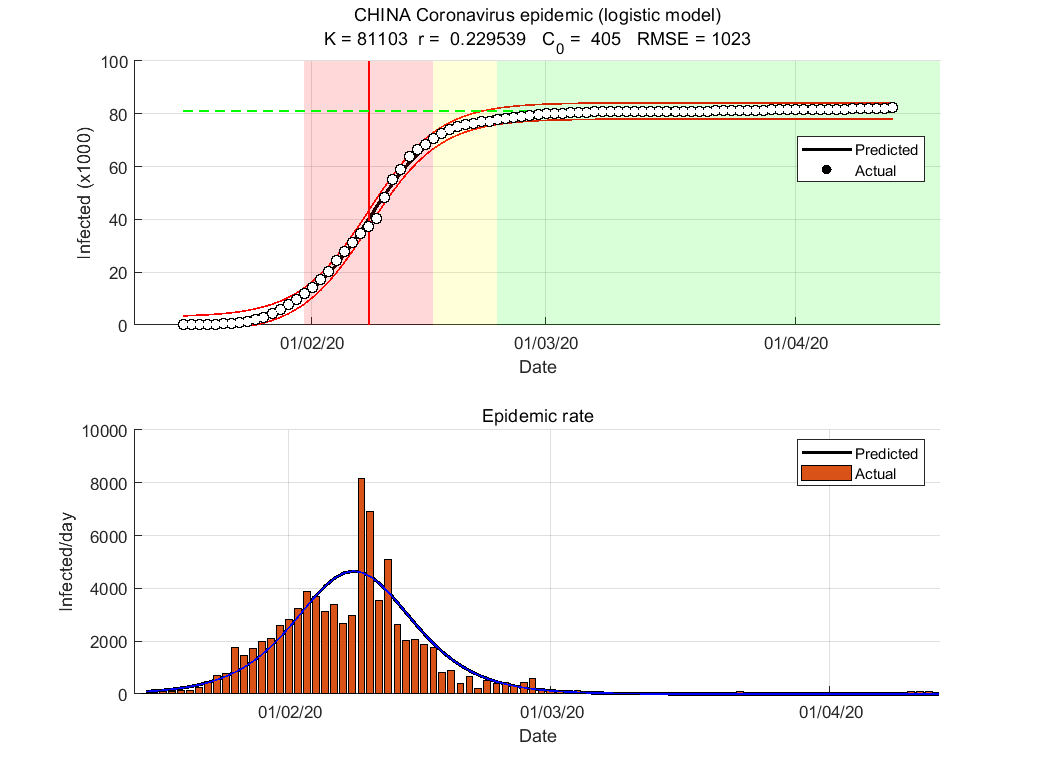


Short-term forecasting for China
 day         date     actual    predict    error % c./day act. c./day pred.     error %
  84  08-Apr-2020      81865      81103       0.93         63          0      100.00
  85  09-Apr-2020      81907      81103       0.98         42          0      100.00
  86  10-Apr-2020      81953      81103       1.04         46          0      100.00
  87  11-Apr-2020      82052      81103       1.16         99          0      100.00
  88  12-Apr-2020      82160      81103       1.29        108          0      100.00
  89  13-Apr-2020      82249      81103       1.39         89          0      100.00
  90  14-Apr-2020 **** Fail: actual > predict


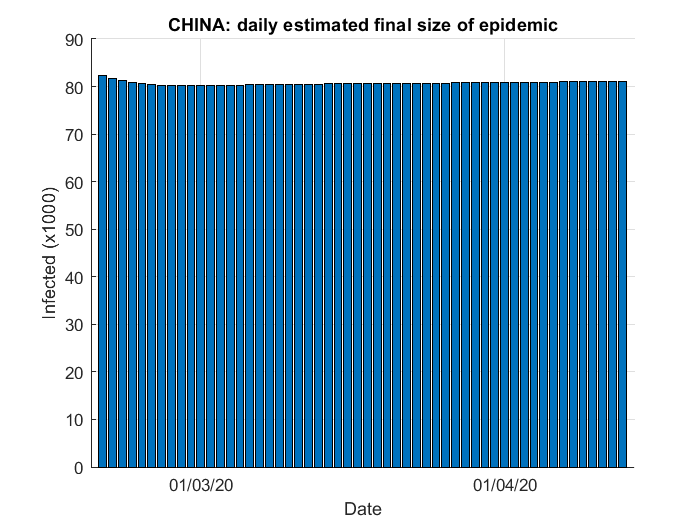

Summary
-------
 date: 13-Apr-2020  day:  89
 start date: 16-Jan-2020 
 number of cases: 82249
 estimated epidemic size (cases): 81103
 estimated epidemic rate (1/day): 2.295392e-01
 estimated initial state (cases): 405
 estimated initial doubling time (day): 3.0
 estimated duration of fast growth phase (day): 17
 estimated peak date: 08-Feb-2020  day: 23 
 estimated peak rate (cases/day): 4654
 estimated end of transition phase: 02-Mar-2020  day: 46
 epidemic phase: 5/5 ending phase
Statistics: total R2 =  0.999, rate R2 =  0.833


fitVirus03(@getDataChina);

## Example 2

Estimate epidemic final size in South Korea

**** Estimation of epidemy size for SouthKorea
  Initial guess K = 10539.2  r = 0.274901  A = 773.271
Regression parameters for complet data set


mdl = Nonlinear regression model:
    y ~ fitVirus03/fun(b,X)

Estimated Coefficients:
         Estimate       SE       tStat       pValue  
         ________    ________    ______    __________

    K     9753.4       116.32    83.849    5.0228e-58
    r    0.21571     0.014321    15.062    8.5139e-21
    A     22.699       4.6881    4.8419    1.1554e-05


Number of observations: 56, Error degrees of freedom: 53
Root Mean Squared Error: 569
R-Squared: 0.975,  Adjusted R-Squared 0.974
F-statistic vs. zero model: 3.56e+03, p-value = 4.29e-61


Evaluation of model parameters for SouthKorea
 day       date        C        K       r    C0   Tau        end  dCdt tpeak       peak    R2
                 (cases)  (cases) (1/day) (cases) (day)            (c/day) (day)           
  23 11-Mar-2020     7869     7944   0.375    83    10 13-Mar-2020   744    12 01-Mar-2020 0.998
  24 12-Mar-2020     7979     7996   0.371    87    10 13-Mar-2020   740    12 01-Mar-2020 0.998
  25 13-Mar-2020     8086     8046   0.367    90    10 13-Mar-2020   737    12 01-Mar-2020 0.998
  26 14-Mar-2020     8162     8090   0.363    93    11 13-Mar-2020   733    12 01-Mar-2020 0.998
  27 15-Mar-2020     8236     8130   0.359    96    11 13-Mar-2020   730    12 01-Mar-2020 0.998
  28 16-Mar-2020     8320     8171   0.356   100    11 13-Mar-2020   726    12 01-Mar-2020 0.998
  29 17-Mar-2020     8413     8215   0.352   104    11 13-Mar-2020   722    12 01-Mar-2020 0.998
  30 18-Mar-2020     8565     8269   0.347   109    11 13-Mar-2020   716    12 01-Mar-20

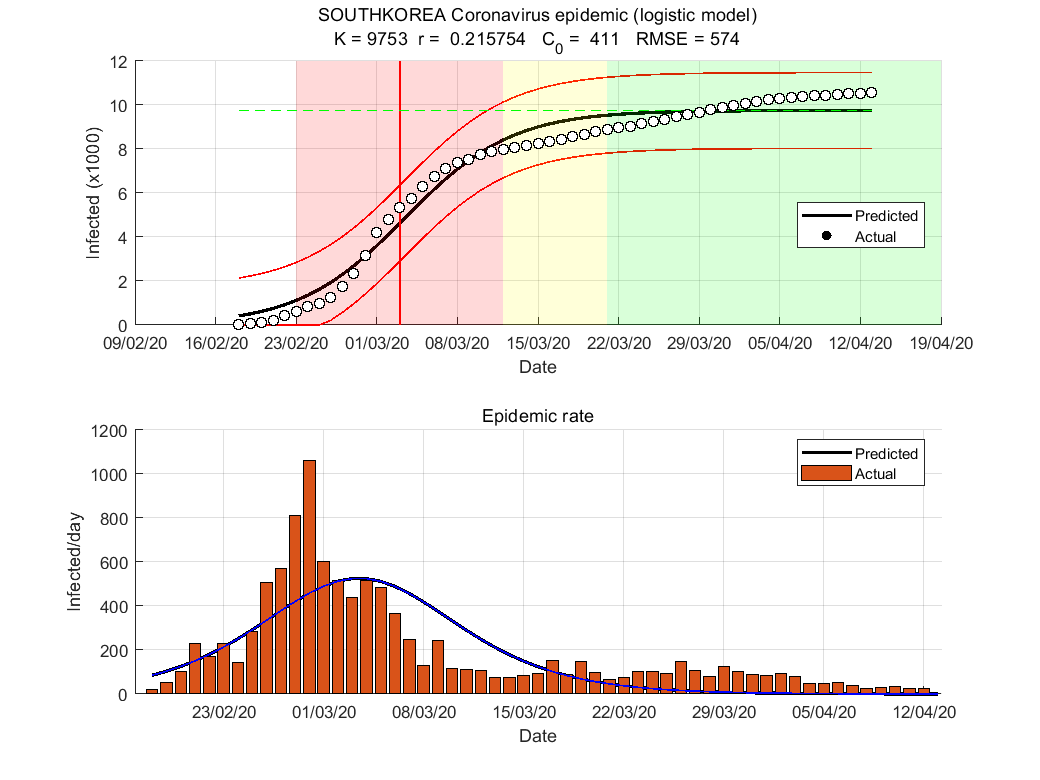


Short-term forecasting for SouthKorea
 day         date     actual    predict    error % c./day act. c./day pred.     error %
  51  08-Apr-2020      10423       9748       6.48         39          1       97.44
  52  09-Apr-2020      10450       9749       6.71         27          1       96.30
  53  10-Apr-2020      10480       9750       6.97         30          1       96.67
  54  11-Apr-2020      10512       9751       7.24         32          1       96.88
  55  12-Apr-2020      10537       9751       7.46         25          0      100.00
  56  13-Apr-2020      10564       9751       7.70         27          0      100.00
  57  14-Apr-2020 **** Fail: actual > predict


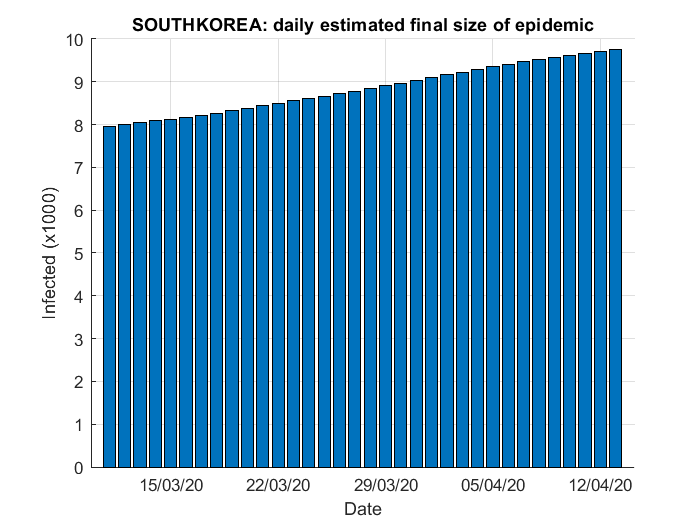

Summary
-------
 date: 13-Apr-2020  day:  56
 start date: 18-Feb-2020 
 number of cases: 10564
 estimated epidemic size (cases): 9753
 estimated epidemic rate (1/day): 2.157543e-01
 estimated initial state (cases): 411
 estimated initial doubling time (day): 3.2
 estimated duration of fast growth phase (day): 18
 estimated peak date: 03-Mar-2020  day: 14 
 estimated peak rate (cases/day): 526
 estimated end of transition phase: 17-Mar-2020  day: 28
 epidemic phase: 5/5 ending phase
Statistics: total R2 =  0.975, rate R2 =  0.616


fitVirus03(@getDataSouthKorea);

## Example 3

Estimate epidemic final size in Italy

**** Estimation of epidemy size for Italy
  Initial guess K = 159757  r = 0.309617  A = 20219.5
Regression parameters for complet data set


mdl = Nonlinear regression model:
    y ~ fitVirus03/fun(b,X)

Estimated Coefficients:
          Estimate        SE        tStat       pValue  
         __________    _________    ______    __________

    K    1.6451e+05       2080.5    79.074    3.4515e-54
    r       0.14823    0.0033867    43.767    1.5583e-41
    A        169.07       15.642    10.809    1.1009e-14


Number of observations: 53, Error degrees of freedom: 50
Root Mean Squared Error: 2.52e+03
R-Squared: 0.998,  Adjusted R-Squared 0.998
F-statistic vs. zero model: 1.71e+04, p-value = 3.02e-75


Evaluation of model parameters for Italy
 day       date        C        K       r    C0   Tau        end  dCdt tpeak       peak    R2
                 (cases)  (cases) (1/day) (cases) (day)            (c/day) (day)           
  22 13-Mar-2020    17660    46676   0.240   183    16 07-Apr-2020  2795    23 15-Mar-2020 0.999
  23 14-Mar-2020    21157   159882   0.375     7    10 13-Apr-2020 14985    26 18-Mar-2020 0.841
  24 15-Mar-2020    24747   159757   0.367     7    10 15-Apr-2020 14664    27 19-Mar-2020 0.847
  25 16-Mar-2020    27980   159755   0.359     7    11 15-Apr-2020 14351    27 19-Mar-2020 0.843
  26 17-Mar-2020    31506  6330290   0.173   442    23 10-Jun-2020 274320    55 16-Apr-2020 0.994
  27 18-Mar-2020    35713    67115   0.226   214    17 11-Apr-2020  3783    25 17-Mar-2020 1.000
  28 19-Mar-2020    41035    77457   0.216   244    18 13-Apr-2020  4190    26 18-Mar-2020 0.999
  29 20-Mar-2020    47021    93561   0.206   287    19 17-Apr-2020  4806    28 20-Mar-2020 0

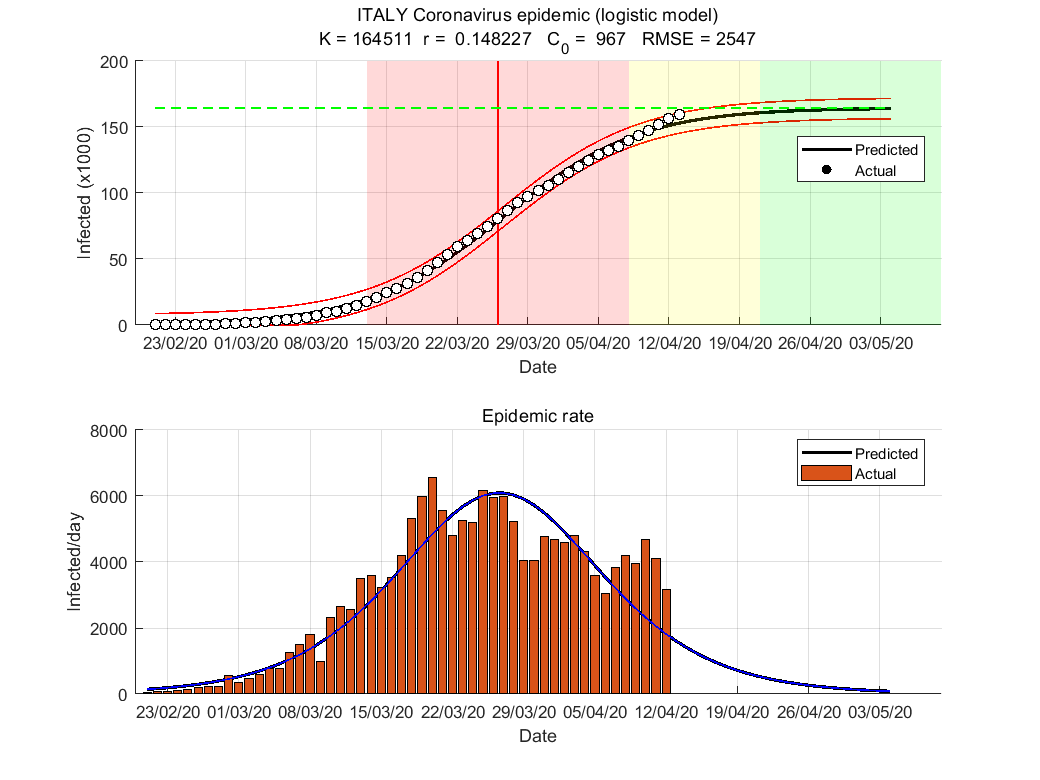


Short-term forecasting for Italy
 day         date     actual    predict    error % c./day act. c./day pred.     error %
  48  08-Apr-2020     139422     141893       1.77       3836       3050       20.49
  49  09-Apr-2020     143626     144632       0.70       4204       2739       34.85
  50  10-Apr-2020     147577     147081       0.34       3951       2449       38.02
  51  11-Apr-2020     152271     149259       1.98       4694       2178       53.60
  52  12-Apr-2020     156363     151190       3.31       4092       1931       52.81
  53  13-Apr-2020     159516     152896       4.15       3153       1706       45.89
  54  14-Apr-2020 **** Fail: actual > predict


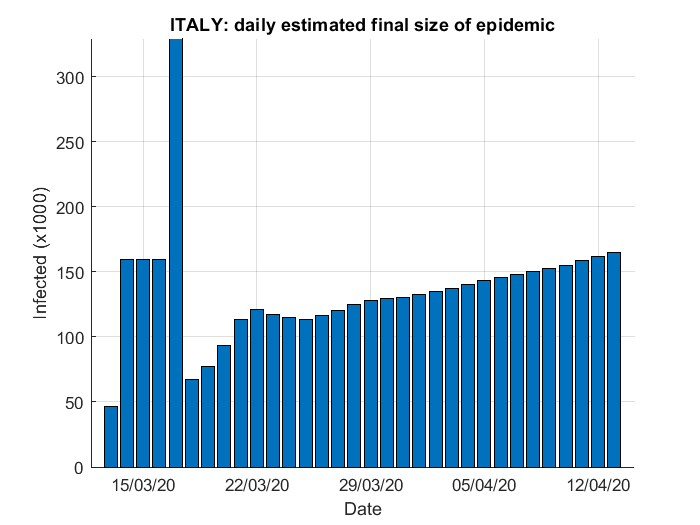

Summary
-------
 date: 13-Apr-2020  day:  53
 start date: 21-Feb-2020 
 number of cases: 159516
 estimated epidemic size (cases): 164511
 estimated epidemic rate (1/day): 1.482267e-01
 estimated initial state (cases): 967
 estimated initial doubling time (day): 4.7
 estimated duration of fast growth phase (day): 26
 estimated peak date: 26-Mar-2020  day: 34 
 estimated peak rate (cases/day): 6096
 estimated end of transition phase: 29-Apr-2020  day: 68
 epidemic phase: 4/5 slow growth transition phase
Statistics: total R2 =  0.998, rate R2 =  0.842


fitVirus03(@getDataItaly);